# Análisis de los experimentos con especies virtuales


PointsAll = [];
CoeffsAll = [];
DistanceAll = [];
AreaMetricAll = [];
RocAll = [];

for i = 1 : 4
%     load("Test/2_5KM/Test" + num2str(i) + "_SA_25_NoAlpha.mat")
    load("Test_KRidge_SA_25_NoAlpha_" + num2str(i) + ".mat")
    PointsAll = [PointsAll; Points];  
    CoeffsAll = [CoeffsAll; Coeffs];
    DistanceAll = [DistanceAll, DistanceMetric];
    AreaMetricAll = [AreaMetricAll, AreaMetric];
    RocAll = [RocAll, Roc];
end

Points = PointsAll;
Coeffs = CoeffsAll;
Distance = DistanceAll;
AreaMetric = AreaMetricAll;
Roc = RocAll;

clear PointsAll CoeffsAll DistanceMetricAll AreaMetricAll RocAll

1. Criterio gráfico

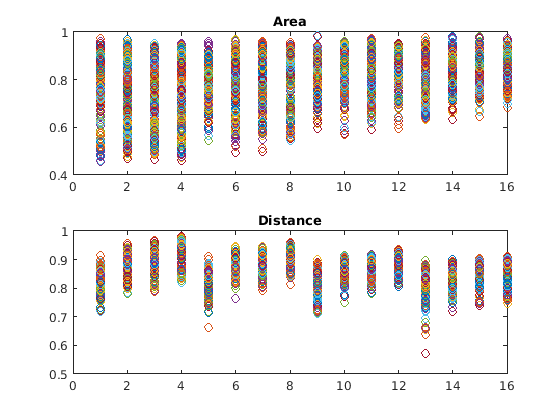

close all
subplot(2,1,1)
plot(AreaMetric, 'o')
title('Area')
subplot(2,1,2)
plot(DistanceMetric, 'o')
title('Distance')

% plot3(OccupExp,SampExp,DistanceMetric, 'o')
% xlabel('OccupExp')
% ylabel('SampExp')
% zlabel('DistanceMetric')

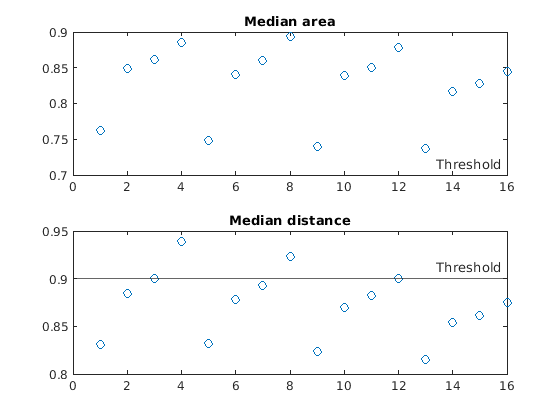

close all
MedianDistance = median(DistanceMetric');
MedianArea = median(AreaMetric');
TresArea = 0.7;
TresDist = 0.9;

subplot(2,1,1)
plot(MedianArea, 'o')
hold on
yline(TresArea,'-','Threshold');
title('Median area')

subplot(2,1,2)
plot(MedianDistance, 'o')
hold on
yline(TresDist,'-','Threshold');
title('Median distance')

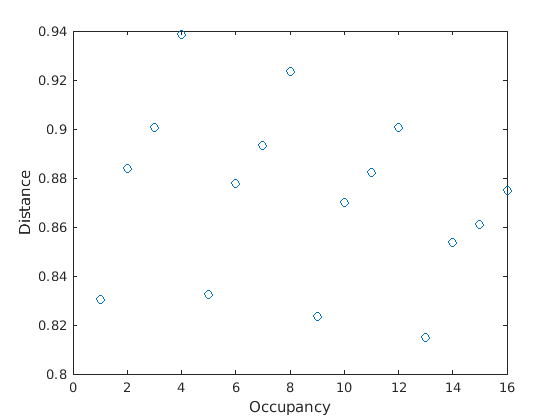

figure
[~, idxOcc] = sort(OccupExp);
plot(MedianDistance(idxOcc),'o');
xlabel('Occupancy')
ylabel('Distance')

## Best Parameter Combination

AreaPoints = find(MedianArea >= TresArea);
DistancePoints = find(MedianDistance >= TresDist);

sum(ismember(AreaPoints, DistancePoints))

ans = 4

Kruskal-Wallis Test

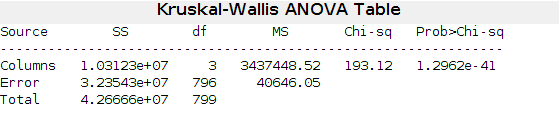

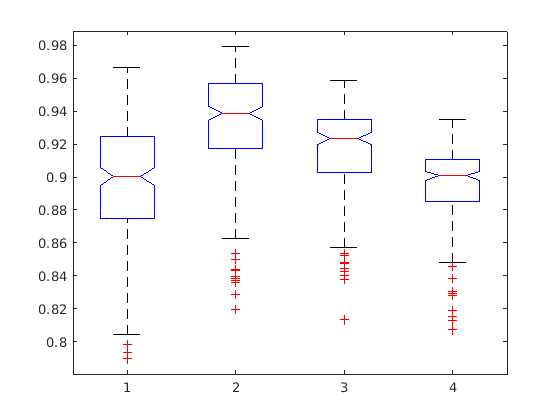

SelectedDistance = DistanceMetric(DistancePoints,:)';
p = kruskalwallis(SelectedDistance);

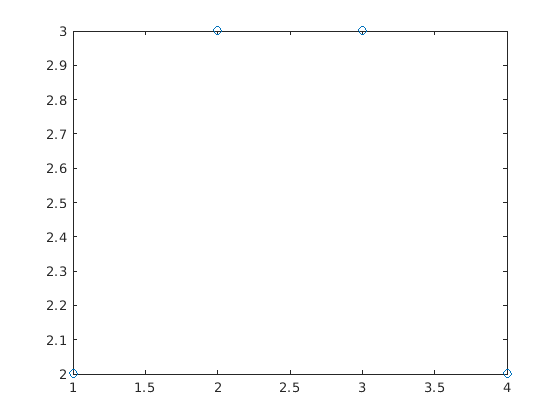

N = length(DistancePoints);
RankSumTestP = zeros(N,N);
RankSumTestBool = zeros(N,N);

for i = 1 : N
    for j = 1 : N
        RankSumTestP(i, j) = ranksum(SelectedDistance(:, i), SelectedDistance(:, j));
        %null hypothesis: data in x and y are samples from continuous distributions with equal medians
        if RankSumTestP(i, j) <= 0.05 %reject null (?)
            RankSumTestBool(i, j) = 1;
        end
    end
end

[Max, idx] = max(mean(SelectedDistance));
Comparation = sum(RankSumTestBool');
plot(Comparation, 'o')

[~, indexBest] = sort(Comparation, 'descend');
for i = 1 : 1
    j = DistancePoints(indexBest(i));
    disp(" ")
    disp("alpha:" + alpExp(j))
    disp("Samples:" + SampExp(j))
    disp("Occupation:" + OccupExp(j))
end

alpha:2


Samples:1000


Occupation:0.1


alpha:2


Samples:1000


Occupation:0.3


## Worst parameter combination

AreaPoints = find(MedianArea < TresArea);
DistancePoints = find(MedianDistance < TresDist);

sum(ismember(AreaPoints, DistancePoints))

ans = 0

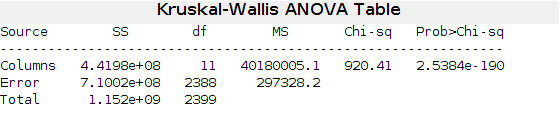

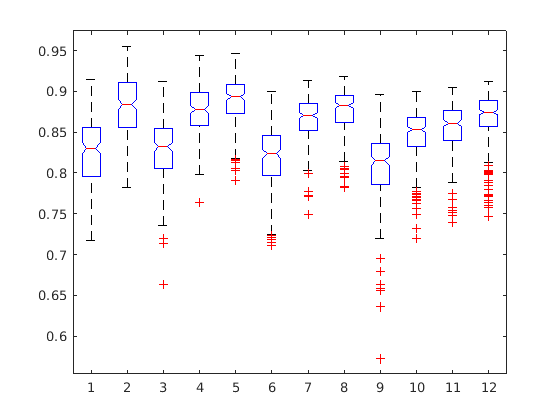

SelectedDistance = DistanceMetric(DistancePoints,:)';
p = kruskalwallis(SelectedDistance);

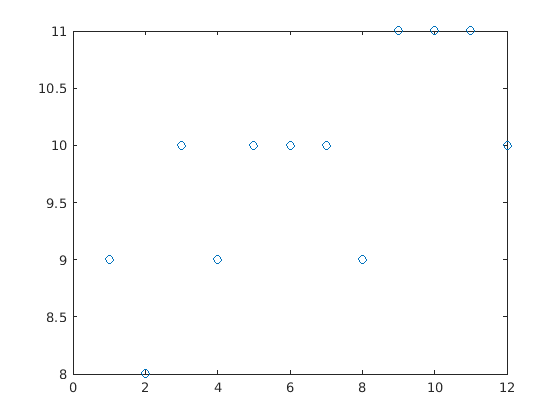

N = length(DistancePoints);
RankSumTestP = zeros(N,N);
RankSumTestBool = zeros(N,N);

for i = 1 : N
    for j = 1 : N
        RankSumTestP(i, j) = ranksum(SelectedDistance(:, i), SelectedDistance(:, j));
        %null hypothesis: data in x and y are samples from continuous distributions with equal medians
        if RankSumTestP(i, j) <= 0.05 %reject null (?)
            RankSumTestBool(i, j) = 1;
        end
    end
end

[Max, idx] = max(mean(SelectedDistance));
Comparation = sum(RankSumTestBool');
plot(Comparation, 'o')

[~, indexBest] = sort(Comparation, 'descend');
for i = 1 : 3
    j = DistancePoints(indexBest(i));
    disp(" ")
    disp("alpha:" + alpExp(j))
    disp("Samples:" + SampExp(j))
    disp("Occupation:" + OccupExp(j))
end

alpha:2


Samples:10


Occupation:0.7


alpha:2


Samples:50


Occupation:0.7


alpha:2


Samples:100


Occupation:0.7


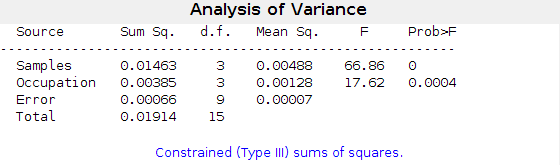

% [~,~,stats] = anovan(mean(DistanceMetric, 2),{SampExp, OccupExp},'model','interaction','varnames',{'Samples','Occupation'});
[~,~,stats] = anovan(mean(DistanceMetric, 2),{SampExp, OccupExp},'model','linear','varnames',{'Samples','Occupation'});

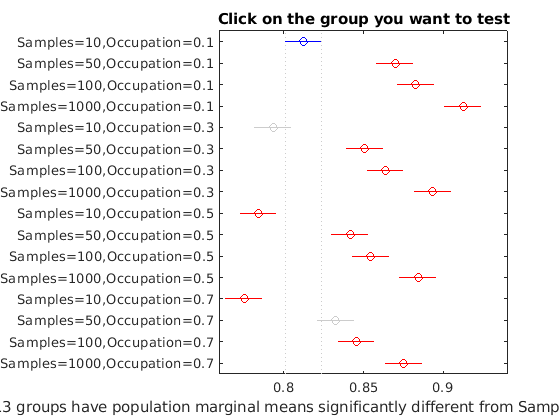

results = multcompare(stats,'Dimension',[1 2]);